clc; clear;


CP = py.importlib.import_module("CoolProp.CoolProp")

CP =   Python module with properties:

                                            PSmass_INPUTS: [1×1 py.int]
                                                 iCvirial: [1×1 py.int]
                                         iGmolar_residual: [1×1 py.int]
                                          iHelmholtzmolar: [1×1 py.int]
                                                  iCpmass: [1×1 py.int]
                              iisothermal_compressibility: [1×1 py.int]
                               set_interaction_parameters: [1×1 py.builtin_function_or_method]
                                      set_reference_state: [1×1 py.builtin_function_or_method]
                      PHASE_ENVELOPE_STARTING_PRESSURE_PA: [1×1 py.int]
                                           iphase_unknown: [1×1 py.int]
                                           TUmolar_INPUTS: [1×1 py.int]
                                                      iFH

tfordamp = -20;
tkond = 35;
middel = "R134a";

underkoling = -5;
Hkond = CP.PropsSI("H","T",273.15 + tkond + underkoling,"Q",0,middel)

Hkond =           241722.392308654


Pkond = CP.PropsSI("P","T",273.15 + tkond,"Q",0,middel)

Pkond =           886980.983608352



Hfordamp = CP.PropsSI("H","T",273.15 + tfordamp,"Q",1,middel)

Hfordamp =           386554.261631309


Pfordamp = CP.PropsSI("P","T",273.15 + tfordamp,"Q",1,middel)

Pfordamp =           132734.979499223



overhedning = 5;
Hkomp = CP.PropsSI("H","T",273.15 + tfordamp + overhedning,"Q",0,middel)

Hkomp =           180137.556076574



format longG

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "R134a";

% for vand
Pmin = CP.PropsSI("P","T",170, "Q", 0, middel)

Pmin =           396.167894782514


Pmax = CP.PropsSI("P","T", 374, "Q", 1, middel)

Pmax =           4042129.37699199


Plin = linspace(Pmin, Pmax, ps);


Tsat_l = zeros(size(Plin));

for i = 1:ps-1
    Tsat_l(i) = CP.PropsSI("T", "P", Plin(i), "Q", 0, middel);
end

hl = zeros(size(Plin));
hg = zeros(size(Plin));
sl = zeros(size(Plin));
sg = zeros(size(Plin));

for j = 1:ps-1
    hl(j) = CP.PropsSI("H","P",Plin(j), "Q", 0, middel);
    hg(j) = CP.PropsSI("H","P",Plin(j), "Q", 1, middel);
    sl(j) = CP.PropsSI("S","P",Plin(j), "Q", 0, middel);
    sg(j) = CP.PropsSI("S","P",Plin(j), "Q", 1, middel);
end


% Fra opgave

h1 = 4.5*1e5;
p1 = 10*1e5;

h2 = 5*1e5;
p2 = 25*1e5;

h3 = 3e5;
p3 = 25*1e5;

h4 = h3;
p4 = p1;

%til plot

hlin1 = linspace(h1,h2,ps-1);
hlin2 = linspace(h2,h3,ps-1);
hlin3 = linspace(h3,h4,ps-1);
hlin4 = linspace(h4,h1,ps-1);
hs = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(p1,p2,ps-1);
plin2 = linspace(p2,p3,ps-1);
plin3 = linspace(p3,p4,ps-1);
plin4 = linspace(p4,p1,ps-1);
pps = [plin1,plin2,plin3,plin4]/1e5;

Tr134a = zeros(size(pps));

for k = 1:length(pps)
    Tr134a(k) = CP.PropsSI("T","H",hs(k),"P",pps(k)*1e5, middel);
end
Tr134a

Tr134a =           341.231866918452           341.95424329298          342.674068830504          343.391373638279          344.106187284418          344.818538810798          345.528456745627           346.23596911566          346.941103458094          347.643886832136           348.34434583025          349.042506589106          349.738394800219          350.432035720303           351.12345418133          351.812674600328          352.499720988884          353.184616962412          353.867385749142           354.54805019887          355.226632791471          355.903155645162          356.577640524553          357.250108848463          357.920581697526           358.58907982159          359.255623646905          359.920233283119          360.582928530082          361.243728884464          361.902653546189          362.559721424696          363.214951145033          363.868361053784          364.519969224834          365.169793464978          365.817851319391          366.464160076935   

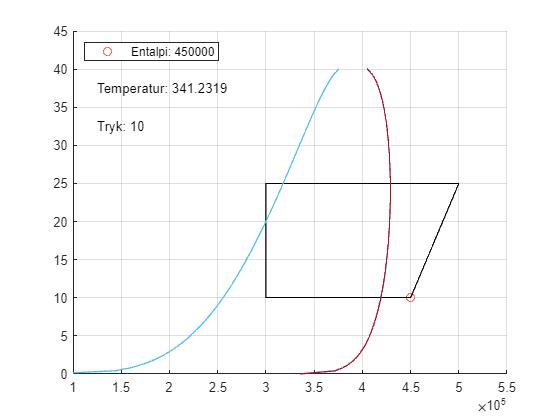


for i = 1:length(hs)

    scatter(hs(i),pps(i),"r")

    xlim([1,5.5]*1e5)

    grid("on")

    hold on

    % Kølekreds
    plot(hlin1,plin1/1e5,"k",hlin2,plin2/1e5,"k",hlin3,plin3/1e5,"k",hlin4,plin4/1e5,"k")

    % PH diagram (ikke log)
    plot(hl(1,1:end-1),Plin(1,1:end-1)/1e5)
    plot(hg(1,1:end-1), Plin(1,1:end-1)/1e5)

    legend("Entalpi: " + hs(i),"Location","northwest")
    
    text(1.25*1e5,37.5,"Temperatur: " + Tr134a(i))
    text(1.25*1e5,32.5,"Tryk: " + pps(i))

    drawnow

    pause(0.05)

    

    hold off
end

clc; clear all;

ps = 100

ps =    100


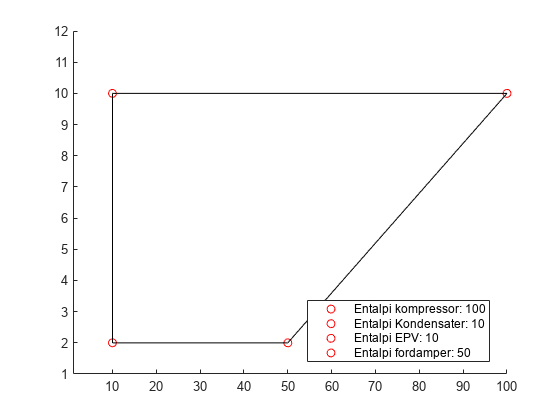

x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);

%plot(x1,y1,"k")



%plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")


for i = 1:ps
    scatter(x1(i),y1(i),"r")
    hold on

    xlim([1,100])
    ylim([1,12])




    scatter(x2(i),y2(i),"r")
    scatter(x3(i), y3(i),"r")
    scatter(x4(i),y4(i),"r")

    plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")

    legend("Entalpi kompressor: " + x1(i), "Entalpi Kondensater: " + x2(i), ...
        "Entalpi EPV: " + x3(i), "Entalpi fordamper: " + x4(i),"Location","best")

    drawnow

    pause(0.05)



    hold off
end

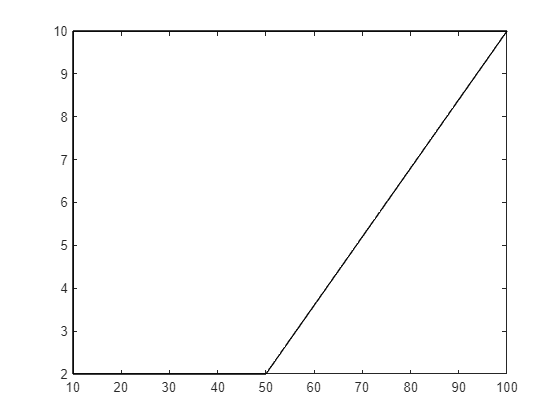

clear all;
ps = 100;
x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);



plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")